# Universidad Autonoma del Estado de México

# Centro Universitario UAEM Zumpango

# Ingenieria en computación

# Profesor: Asdrubal Lopéz Chau

# Alumnos:

# Jordan Jair Hernandez Cantero

# Amaury Fabian Miguel Castillo

# Proyecto de ciencia de los datos

# Noviembre 2022

## Conjunto de datos

El data set utilizado en este caso de estudio contiene información relacionada con el sueldo que perciben los profesionistas del área de Ciencia de los datos y los distintos campos subyacentes del área ya mencionada. En el cual es posible encontrar variables como:

1) Año en que se registró el sueldo percibido

2) Nivel de experiencia, dividido en niveles de experiencia:

- EN: Entry Level (Nivel inicial o de entrada)

- MI: Mid Level (Nivel medio)

- SE: Senior Level (Nivel avanzado)

- EX: Executive Level (Nivel ejecutivo)

3) Tipo de empleado: 

- PT: Partial Time (Tiempo parcial o medio tiempo)

- FT: Full Time (Tiempo completo)

- CT: Contract (Contrato)

- FL: Freelance 

4) Job title (Titulo o especialidad)

5) Salario

6) Moneda del pais

7) Salario en dolares

8) Lugar de residencia del empleado

9) Remote ratio

10) Ubicación de la compania

11) Tamaño de la empresa

Con un total de 606 registros, los cuales nos permitirán responder algunas de las preguntas, que nos planteamos como equipo. Y se puede encontrar en el siguiente link:

[https://www.kaggle.com/datasets/ruchi798/data-science-job-salaries](https://www.kaggle.com/datasets/ruchi798/data-science-job-salaries)

## Preguntas

Las preguntas descritas más adelante tienen la finalidad de comprender como se manejan los salarios de los empleados del área de ciencia de los datos, teniendo en cuenta distintos factores como la experiencia, tamaño de la empresa o la especialidad que se tiene. (Preguntas descriptivas).

1) ¿De que país son las empresas que mas pagan?

2) ¿Tiene influencia la experiencia en el sueldo persibido?

3) ¿De  que país son la  mayoría de empleados?

4) ¿Tiene relación el tamaño de la empresa con los salarios?

5) ¿Que titulo o especialidad  gana mas?

## Análisis Exploratorio

## Leemos los datos de nuestro conjunto de datos:

T = readtable('../Data/ds_salaries.csv')

T = 607×12 table
    Var1    work_year    experience_level    employment_type              job_title                salary     salary_currency    salary_in_usd    employee_residence    remote_ratio    company_location    company_size
    ____    _________    ________________    _______________    ______________________________    ________    _______________    _____________    __________________    ____________    ________________    ____________

      0       2020            {'MI'}             {'FT'}         {'Data Scientist'            }       70000        {'EUR'}              79833

### Comprobamos el empaquetado:

%Dimensiones generales
size(T)

ans =    607    12


%Dimensiones con columnas y filas
[numF,numC] = size(T)

numF = 607

numC = 12

summary(T)

Variables:

    Var1: 607×1 double

        Values:

            Min           0   
            Median      303   
            Max         606   

    work_year: 607×1 double

        Values:

            Min         2020  
            Median      2022  
            Max         2022  

    experience_level: 607×1 cell array of character vectors

    employment_type: 607×1 cell array of character vectors

    job_title: 607×1 cell array of character vectors

    salary: 607×1 double

        Values:

            Min           4000
            Median    1.15e+05
            Max       3.04e+07

    salary_currency: 607×1 cell array of character vectors

    salary_in_usd: 607×1 double

        Values:

            Min             2859
            Median    1.0157e+05
            Max            6e+05

    employee_residence: 607×1 cell arr

### Preparamos los datos para su posterior uso.

data = T(:,{'work_year','experience_level','job_title','employment_type','company_location','company_size','employee_residence'});
%data.work_year = datetime(data.work_year);
data.job_title = categorical(data.job_title);
data.experience_level = categorical(data.experience_level);
data.employee_residence = categorical(data.employee_residence);
data.company_location = categorical(data.company_location);
data.company_size = categorical(data.company_size);
%find(data.job_title == 'Data Analyst')
%Promedio de salarios en dolares

Promedio general de los salarios en dolares:

mean(T.salary_in_usd)

ans = 1.1230e+05

## Análisis de los datos

1) ¿De que país son las empresas que mas pagan?

Como se puede observar en la gráfica que se muestra está muy claro que en su mayoría las empresas registradas residen en USA (Estados Unidos de Norte América), o por lo menos su cede principal se encuentra en dicho país, lo que por ende nos deja con un mayor promedio en los salarios de los trabajadores siendo este de:

usas = find(data.company_location=="US");
usas = T(find(data.company_location=="US"),"salary_in_usd");
usp = mean(usas.salary_in_usd)

usp = 1.4406e+05

Con un total de registros:

[numF, numC] = size(usas);
numF

numF = 355

gscatter(data.company_location,T.salary_in_usd)
title("Sueldos por ubicación de la empresa")
xlabel("Paises")
ylabel("Salario en dolares")

De este modo es fácil de entender que los mejores sueldos para los profesionistas del área de ciencia de los datos se encuentran en USA, aunque faltaría más información debido a que esto es solo un factor. Que podría influir en lo que se refiere al sueldo, también están la experiencia del trabajador, el tamaño de la compañía y probablemente el país en el que vive el empleado. 

2) ¿Tiene influencia la experiencia en el sueldo persibido?

A simple vista pueden resultar un tanto engañosos los datos observados en la gráfica, ya que parecería que aquellos empleados en el nivel senior (SE) son los mejor pagados, pero tras analizar un poco más a fondo los datos podemos observar otra información distinta:

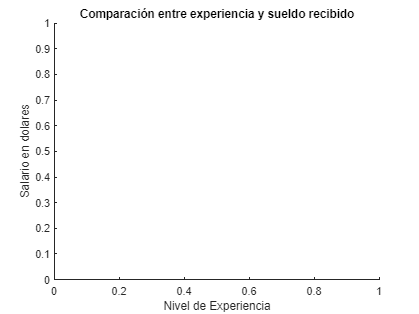

gscatter(data.experience_level,T.salary_in_usd)
xlabel("Nivel de Experiencia")
ylabel("Salario en dolares")

title("Comparación entre experiencia y sueldo recibido")
EN = find(data.experience_level =="EN");
EN = T(find(data.experience_level =="EN"),"salary_in_usd");
EN = mean(EN.salary_in_usd);

EX = find(data.experience_level =="EX");
EX = T(find(data.experience_level =="EX"),"salary_in_usd");
EX = mean(EX.salary_in_usd);

MI = find(data.experience_level =="MI");
MI = T(find(data.experience_level =="MI"),"salary_in_usd");
MI = mean(MI.salary_in_usd);

SE = find(data.experience_level =="SE");
SE = T(find(data.experience_level =="SE"),"salary_in_usd");
SE = mean(SE.salary_in_usd);

gr = [EN,MI,SE,EX];
figure;
X = categorical({'EN','MI','SE','EX'});
bar(X,gr)

En la gráfica superior se observan los salarios que cada empelado tiene en función de la experiencia que se tiene, pero en el segundo están comparados los promedios de los salarios, dando como vencedores a los de mayor experiencia, es decir se puede observar que existe una relación entre la experiencia que se tiene como trabajador y el sueldo que tienes.

3) ¿De  que país son la  mayoría de empleados?

A continuación, se observa el país de origen de los empleados registrados en los datos, con esto trataremos de observar si existe algún tipo de relación entre el país de origen del trabajador y el país de origen de la empresa.

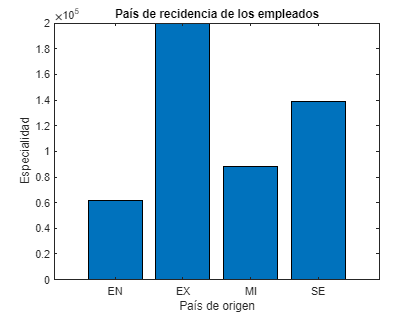

gscatter(data.employee_residence,data.job_title)
title("País de recidencia de los empleados")
xlabel("País de origen")

ylabel("Especialidad")
n =find(data.employee_residence =="US");
b = size(n);
s = size(data);
di = (s)- n;
a = size(di);
gr = [b,a];
figure;
pie(gr)
labels = {'US','Resto del mundo'};
legend(labels,'Location','southoutside','Orientation','horizontal')

Como se observa en la grafica de pastel, los datos que tenemos provienen en un 50% de personas que segun los datos viven en USA, por lo que no lo mas acerto afirmar que el país donde vives puede influir en el sueldo que puedas obtener, es decir se necesitaria datos mas variados para poder dar una opinion objetiva acerca si esto es un factor que afecta o no.

4) ¿Tiene relación el tamaño de la empresa con los salarios?

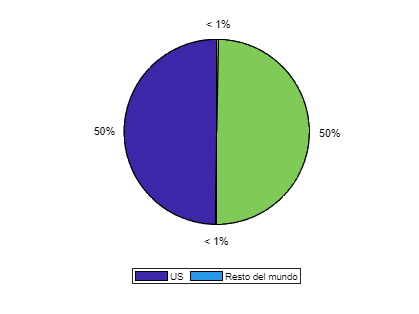

gscatter(data.company_size,T.salary_in_usd)
xlabel("Tamaño de Empresa")

ylabel("Sueldo en dolares")

En la grafica de dispersion por grupos se puede observar que  


ss =find(data.company_size =="S");
ss =T(find(data.company_size =="S"),8);

ss = 83×1 table
    salary_in_usd
    _____________

        2.6e+05  
          20000  
        1.9e+05  
       1.25e+05  
          51321  
          41689  
     1.1405e+05  
          33511  
          59303  
          10000  
       1.38e+05  
          45760  
          15966  
          76958  
           6072  
          45896  


sm =find(data.company_size =="M");
sm =T(find(data.company_size =="M"),8);

sm = 326×1 table
    salary_in_usd
    _____________

     1.0902e+05  
          39916  
           5707  
          56000  
          43331  
          98000  
        4.5e+05  
          50180  
     1.4826e+05  
          38776  
       1.18e+05  
     1.3835e+05  
      1.308e+05  
      1.902e+05  
          1e+05  
           5409  


sl =find(data.company_size =="L");

sl =      1
     5
     6
     8
     9
    12
    14
    15
    16
    22


sl =T(find(data.company_size =="L"),8);

sl = 198×1 table
    salary_in_usd
    _____________

          79833  
        1.5e+05  
          72000  
          35735  
       1.35e+05  
          40481  
          87000  
          85000  
           8000  
           6072  
          47899  
       1.15e+05  
       3.25e+05  
          42000  
          1e+05  
      1.171e+05  


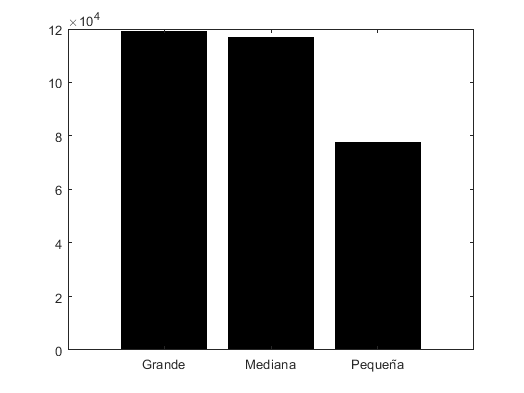


Ms = mean(ss.salary_in_usd);
Mm = mean(sm.salary_in_usd);
Ml = mean(sl.salary_in_usd);
Maxs = max(ss.salary_in_usd);
Mins = min(ss.salary_in_usd);
Maxm = max(sm.salary_in_usd);
Minm = min(sm.salary_in_usd);
Maxl = max(sl.salary_in_usd);
Minl = min(sl.salary_in_usd);
gr = [Ms,Mm,Ml];
figure;
X0 = categorical({'Pequeña','Mediana','Grande'});
bar(X0,gr,'black')

-Salarios promedio por tamaño de la empresa

- Empresa Grande 119,243 dolares

- Empresa Mediana 116,905 dolares

- Empresa Pequeña 77,632 dolares

gr = [Maxs,Mins,Maxm,Minm,Maxl,Minl];
figure;
X = categorical({'Maximo Pequena','Minimo Pequena','Maximo Mediana','Minimo Mediana','Maximo Grande','Minimo Grande'});
bar(X,gr,'green')

En la grafica de barras se puede observar los sueldos maximos y minimos dependiendo del tamaño de la empresa

- Salario mas alto en una empresa grande 600,000

- Salario mas alto en una empresa mediana 450,000

- Salario mas alto en una empresa pequeña 416,000

- Salario mas bajo en una empresa grande 5,882

- Salario mas bajo en una empresa mediana 4,000

- Salario mas bajo en una empresa pequeña 2,859

-Se puede observar que entre una empresa pequeña y una mediana los sueldos mas altos no tienen una diferencia considerable, pero el suledo mas alto en una empresa grande si tiene una diferencia considerable

 -Los sueldos mas bajos que hay en cada grupo tambien tienen diferencias considerables

Por lo tanto se puede concluir que el tamaño de la empresa si tiene relacion con los salarios maximos que se pueden alcanzan y los salarios promedio dependiendo del tamaño de la empresa

5) ¿Que titulo o especialidad  gana mas?

Por último, comprobamos cuales son las especialidades que mejor sueldo perciben.

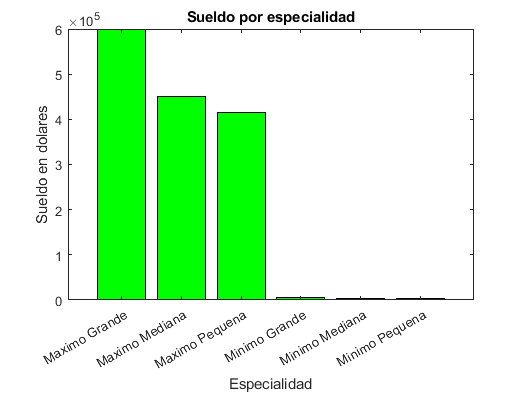

gscatter(data.job_title,T.salary_in_usd)
title("Sueldo por especialidad")
xlabel("Especialidad")

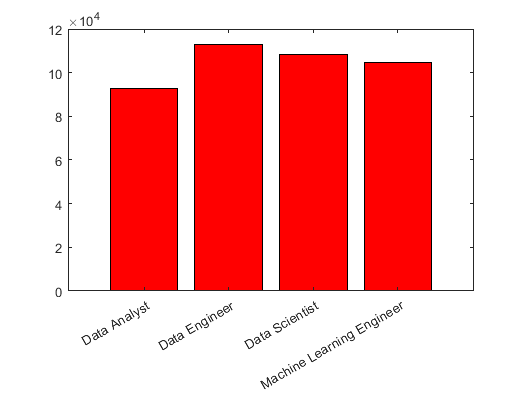

ylabel("Sueldo en dolares")
de = find(data.job_title =="Data Engineer");
de = T(find(data.job_title == "Data Engineer"),"salary_in_usd");
de = mean(de.salary_in_usd);

dc = find(data.job_title=="Data Scientist");
dc = T(find(data.job_title=="Data Scientist"),"salary_in_usd");
dc = mean(dc.salary_in_usd);

da = find(data.job_title=="Data Analyst");
da = T(find(data.job_title=="Data Analyst"),"salary_in_usd");
da = mean(da.salary_in_usd);

me = find(data.job_title=="Machine Learning Engineer");
me = T(find(data.job_title=="Machine Learning Engineer"),"salary_in_usd");
me = mean(me.salary_in_usd);

gr = [de,dc,da,me];
figure;
X = categorical({'Data Engineer','Data Scientist','Data Analyst','Machine Learning Engineer'});

bar(X,gr,'red')

Tras la exploración de los datos podemos concluir que las cuatro especialidades con mejores sueldos son las que se observan en las gráficas

- Data Analyst 92,893 dolares

- Data Engineer 112,725 dolares

- Data Scientist 108,188 dolares

- Machine Learning Engineer 104,880 dolares

## Hallazgos

Por último, después de manipular los datos es posible decir que los factores que más afectan al salario que un trabajador del área de ciencia de los datos, son la experiencia que tengas esto quiere decir que a mayor experiencia mejor es el sueldo que puedes obtener, otro punto a considerar es el hecho que las empresas que mejores salarios ofrecen son de USA, algo que al final tiene sentido ya que las compañías más grandes del mundo tienen sede en este país por lo que era de esperar, también se encontró que los salarios si tienen una relación con el tamaño de la empresa, ya que las empresas mediana y grandes tienen sueldos promedio mejores que las pequeñas empresas y los salarios más altos se encuentran en las empresas grandes, así mismo si se tiene interés en alguna de estas especialidades quizás sea bueno saber que las que mejores sueldos tienen en promedio son:

- Analista de datos (Data Analyst)

- Ingeniero de datos (Data Engineer)

- Científico de datos (Data Scientist)

- Ingeniero en Machine Learning ( Machine Learning Engineer) 

Todas con promedios muy cercanos siendo la de ingeniero de datos la que llega a sobresalir.